close("all"); clear; clc;
addpath("prydeMotorcycleStateSpace\");

Cdelta = 6.77;
Ibxx = 31.18;
Ibxz = -1.7355;
Ibzz = 21.07;
Ihxx = 1.2338;
Ihzz = 0.442;
v = 80/3.6;
Zf = 1.2E03;
Zr = 1.5E03;
a = 0.9485376;
b = 0.4798;
e = 0.0244;
f = 0.0283;
g = -9.80665;
h = 0.6157;
ify = 0.7186;
iry = 1.0508;
kaf = 10;
kar = 10;
kkf = 12;
kkr = 12;
klf = 0.7;
klr = 0.7;
mb = 217.45;
mh = 30.65;
rf = 0.3048;
rr = 0.3048;
tf = 0;
tr = 0;
caster = -0.4715;

an = 0.1158;
lx = rf*sin(-caster) - an;
c = cos(-caster);
s = sin(-caster);
lz = -(rf*c^2 + (an - a)*s)/c;

params = [
    Cdelta;
    Ibxx;
    Ibxz;
    Ibzz;
    Ihxx;
    Ihzz;
    v;
    Zf;
    Zr;
    a;
    b;
    e;
    f;
    g;
    h;
    ify;
    iry;
    kaf;
    kar;
    kkf;
    kkr;
    klf;
    klr;
    lx;
    lz;
    mb;
    mh;
    rf;
    rr;
    tf;
    tr;
    caster
    ];

sys = prydeMotorcycleStateSpace(params);
eig(sys.a)

ans = 1.0e+02 *

  -1.1569 + 0.0000i
   0.9113 + 0.0000i
  -0.0833 + 0.4906i
  -0.0833 - 0.4906i
  -0.0754 + 0.1007i
  -0.0754 - 0.1007i
   0.8180 + 0.0000i
   0.6771 + 0.0000i
  -0.0000 + 0.0000i


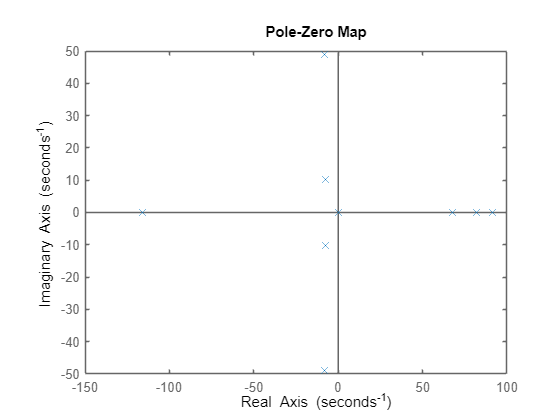

pzmap(sys)

rmpath("prydeMotorcycleStateSpace\")